%% Clasificación de dígitos MNIST con SOM (Self‑Organizing Map)

%% 1) Configuración inicial
clc; clear; close all;
rng(42);  % Para reproducibilidad

%% 2) Carga de datos
load('digits.mat');                 % Carga digits.image (784×10000), digits.label (1×10000)
X = digits.image;                   % Cada columna es una muestra (784 características)
Y = digits.label + 1;               % Etiquetas de 0–9 → 1–10

%% 3) División train/test (80/20)
num_samples = size(X,2);
idx = randperm(num_samples);
nTrain = round(0.8 * num_samples);
trainIdx = idx(1:nTrain);
testIdx  = idx(nTrain+1:end);

Xtrain = X(:, trainIdx);
Ytrain = Y(trainIdx);
Xtest  = X(:, testIdx);
Ytest  = Y(testIdx);

%% 4) Normalización y PCA
[Xtrain_n, ps] = mapstd(Xtrain);                    % Normalizar training
Xtest_n = mapstd('apply', Xtest, ps);               % Normalizar test igual

% PCA para reducir a 50 dimensiones
[coeff, scoreTrain, ~, ~, ~] = pca(Xtrain_n');

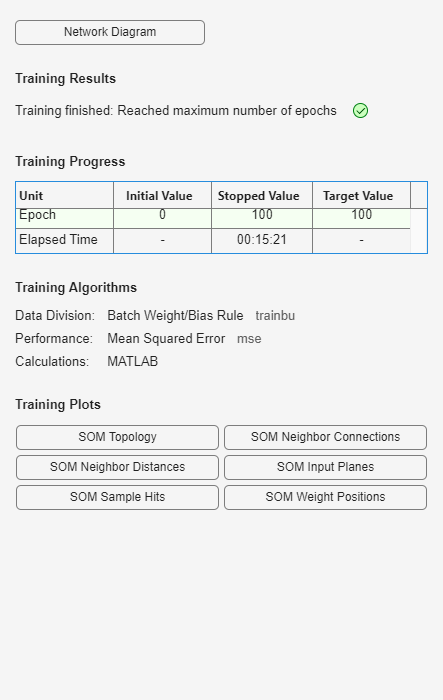

scoreTest = (Xtest_n' - mean(Xtrain_n')) * coeff;

nComp = 50;                                         % Número de componentes
Xtrain_n = scoreTrain(:, 1:nComp)';                 % Transponer para usar en SOM
Xtest_n  = scoreTest(:,  1:nComp)';

%% 5) Entrenamiento del SOM
gridSize = [50 50];                                 % Tamaño de la rejilla de neuronas
net = selforgmap(gridSize);
net.trainParam.epochs = 100;                        % Más épocas para mejor ajuste
net.trainParam.showWindow = true;
net = train(net, Xtrain_n);


%% 6) Etiquetado de neuronas (por mayoría)
Ytrain_act = net(Xtrain_n);
bmus_train = vec2ind(Ytrain_act);

numNeurons = prod(gridSize);
neuronLabels = -1 * ones(1, numNeurons);            % -1: sin etiqueta

for n = 1:numNeurons
    members = (bmus_train == n);
    if any(members)
        labels = Ytrain(members);
        neuronLabels(n) = mode(labels);
    end
end

% Asignar clase global a neuronas sin etiqueta
global_mode = mode(Ytrain);
neuronLabels(neuronLabels == -1) = global_mode;

%% 7) Clasificación del set de test
Ytest_act = net(Xtest_n);
bmus_test = vec2ind(Ytest_act);
Ypred_som = neuronLabels(bmus_test);

%% 8) Métricas de rendimiento
accuracy_som = sum(Ypred_som == Ytest) / numel(Ytest);
fprintf('Accuracy SOM en test: %.2f%%\n', accuracy_som*100);

Accuracy SOM en test: 84.00%


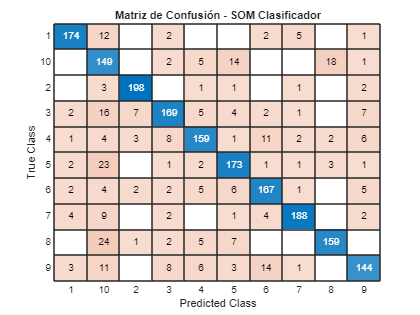


% Matriz de confusión
classes = 1:10;
C = confusionmat(Ytest, Ypred_som, 'Order', classes);

figure;
confusionchart(C, string(classes));
title('Matriz de Confusión - SOM Clasificador');

%% 9) Mapa visual del SOM: imagen patrón por neurona
% Para cada neurona, muestra una imagen representativa (más cercana)

imageSize = [28 28];   % Tamaño original de las imágenes MNIST
mapH = gridSize(1);
mapW = gridSize(2);

% Inicializar figura
figure('Name','Mapa Visual del SOM','Color','w');
colormap gray;

% Obtener BMUs de entrenamiento
Ytrain_act = net(Xtrain_n);
bmus_train = vec2ind(Ytrain_act);

% Crear matriz para visualizar
for i = 1:mapH
    for j = 1:mapW
        neuronIndex = sub2ind(gridSize, i, j);
        % Encuentra todas las muestras asignadas a esta neurona
        samplesIdx = find(bmus_train == neuronIndex);
        if ~isempty(samplesIdx)
            % Tomamos la primera muestra asociada como representativa
            sampleImage = reshape(Xtrain(:, samplesIdx(1)), imageSize);
            % Mostrar la imagen en su posición
            subplot(mapH, mapW, neuronIndex);
            imagesc(sampleImage);
            axis off;
        else
            % Neuronas sin asignación: mostrar blanco
            subplot(mapH, mapW, neuronIndex);
            imagesc(ones(imageSize));
            axis off;
        end
    end
end

sgtitle('Mapa Visual del SOM: Imagen Patrón por Neurona');
